disp("Start simulation of model")

Start simulation of model



%Initialise data and filter
load mpuCali.mat sensorCalibration60
sensorData = array2table(sensorCalibration60, 'VariableNames', ["time", "gx", "gy", "gz", "ax", "ay", "az", "mx", "my", "mz"])

sensorData = 600×10 table
    time      gx       gy       gz      ax    ay     az       mx       my       mz  
    _____    _____    _____    _____    __    __    ____    ______    _____    _____

    10338     0.11     0.04     0.08    0     0     1.01    -34.15    -6.81       42
    10439     0.31     0.08    -0.09    0     0     1.01     -35.2    -7.51    41.66
    10540     0.08     0.04     0.08    0     0     1.01    -35.55    -7.51    40.65
    10640     0.15     0.15      0.1    0     0     1.01    -35.55    -7.85    41.33
    10741     0.17     0.04     0.03    0     0     1.01    -34.15    -7.51    44.03
    10843     0.09     0.22     0.13  

sensorData.time = sensorData.time/1000

sensorData = 600×10 table
     time      gx       gy       gz      ax    ay     az       mx       my       mz  
    ______    _____    _____    _____    __    __    ____    ______    _____    _____

    10.338     0.11     0.04     0.08    0     0     1.01    -34.15    -6.81       42
    10.439     0.31     0.08    -0.09    0     0     1.01     -35.2    -7.51    41.66
     10.54     0.08     0.04     0.08    0     0     1.01    -35.55    -7.51    40.65
     10.64     0.15     0.15      0.1    0     0     1.01    -35.55    -7.85    41.33
    10.741     0.17     0.04     0.03    0     0     1.01    -34.15    -7.51    44.03
    10.843     0.09     0.22   

Fs = 10;
acceleration = [sensorData.ax sensorData.ay sensorData.az]

acceleration =          0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100


gyroscope = [sensorData.gx sensorData.gy sensorData.gz]

gyroscope =     0.1100    0.0400    0.0800
    0.3100    0.0800   -0.0900
    0.0800    0.0400    0.0800
    0.1500    0.1500    0.1000
    0.1700    0.0400    0.0300
    0.0900    0.2200    0.1300
   -0.2400    0.1100    0.1600
    0.0200   -0.1300   -0.0700
   -0.2700    0.0200    0.0700
    0.1100    0.0100   -0.0300


magnetometer = [sensorData.mx sensorData.my sensorData.mz]

magnetometer =   -34.1500   -6.8100   42.0000
  -35.2000   -7.5100   41.6600
  -35.5500   -7.5100   40.6500
  -35.5500   -7.8500   41.3300
  -34.1500   -7.5100   44.0300
  -35.0200   -7.3300   41.5000
  -34.3200   -8.0300   42.5100
  -35.9000   -8.5500   43.3500
  -33.9700   -6.6300   42.1700
  -35.3800   -6.2800   42.8500


decim = 1;
time = sensorData.time

time =    10.3380
   10.4390
   10.5400
   10.6400
   10.7410
   10.8430
   10.9430
   11.0450
   11.1460
   11.2460


fuse = ahrsfilter("SampleRate", 10, "DecimationFactor", decim);
limit = length(time);

q = fuse(acceleration(2:limit, :), gyroscope(2:limit, :), magnetometer(2:limit, :))

q = 599×1 quaternion array
        0.10941 +  0.0026748i +   0.016338j +    0.99386k
        0.10556 +    0.00522i +   0.020742j +    0.99418k
        0.10085 +  0.0020907i +    0.02873j +    0.99448k
       0.099986 +  0.0043346i +   0.036771j +     0.9943k
       0.094034 -   0.003316i +   0.041352j +     0.9947k
       0.086994 -   0.006758i +   0.029124j +    0.99576k
       0.091983 +  0.0016062i +   0.028389j +    0.99535k
       0.089339 +  0.0017604i +   0.014638j +    0.99589k
       0.091622 +  0.0036589i +   0.019423j +     0.9956k
       0.098556 - 0.00018338i +   0.036069j +    0.99448k
       0.093076 -  0.0031564i +   0.029679j +    0.99521k
       0.095402 -  0.0047876i +   0.046931j +    0.99432k
       0.093682 -  0.0030202i +    0.04776j +    0.99445k
       0.099188 - 0.00092283i +   0.037273j +    0.99437k
        0.10245 +  0.0037543i +    0.02527j +    0.99441k
         0.1031 +  0.0077834i +   0.021267j +    0.99441k
        0.10341 +    0.01082i +   0.021119j +

g = [0 0 1.01];
qg = quaternion([0 g]);
g_ = q(:).*qg;
g_ = g_.*q(:).conj

g_ = 599×1 quaternion array
              0 +  0.0089807i +   0.032209j +     1.0094k
              0 +   0.014906i +   0.040542j +     1.0091k
              0 +   0.010053i +   0.057289j +     1.0083k
              0 +   0.016133i +   0.072979j +     1.0072k
    -1.3878e-17 +  0.0011919i +   0.083719j +     1.0065k
     1.3878e-17 -  0.0084755i +   0.059768j +     1.0082k
     1.3878e-17 +  0.0085044i +   0.056782j +     1.0084k
              0 +   0.006183i +   0.029129j +     1.0096k
              0 +   0.010953i +   0.038385j +     1.0092k
              0 +  0.0068124i +   0.072494j +     1.0074k
    -1.3878e-17 - 0.00076528i +   0.060259j +     1.0082k
     1.3878e-17 - 0.00057181i +   0.095185j +     1.0055k
              0 +  0.0029711i +   0.096512j +     1.0054k
              0 +  0.0056145i +   0.075053j +     1.0072k
     1.3878e-17 +   0.012771i +   0.049983j +     1.0087k
              0 +   0.020064i +   0.041099j +      1.009k
              0 +   0.026145i +    0.04016j 


[r,x,y,z] = parts(g_);

% calculate position
acceleration(2:limit,:) = acceleration(2:limit,:) 

acceleration =          0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100


acceleration(2:limit,:) = acceleration(2:limit,:) - [x(1:limit-1) y(1:limit-1) z(1:limit-1)];
acceleration(2:limit,:) = acceleration(2:limit,:) - mean(acceleration)

acceleration =          0         0    1.0100
   -0.0210   -0.0380   -0.0124
   -0.0269   -0.0463   -0.0121
   -0.0221   -0.0631   -0.0113
   -0.0282   -0.0788   -0.0102
   -0.0132   -0.0895   -0.0095
   -0.0036   -0.0655   -0.0112
   -0.0205   -0.0626   -0.0114
   -0.0182   -0.0349   -0.0125
   -0.0230   -0.0442   -0.0122


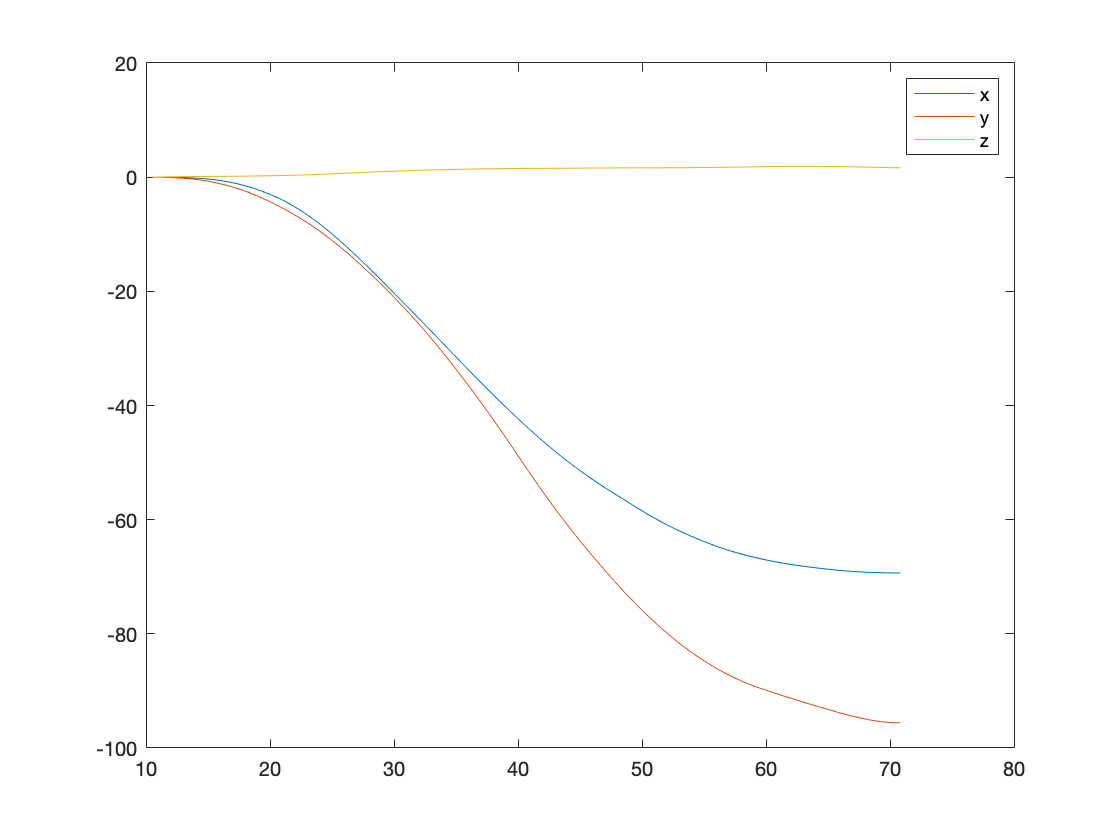

velocity = zeros(length(acceleration), 3);
for i = 2:length(acceleration) 
        velocity(i,:) = velocity(i-1,:) + (acceleration(i,:)+acceleration(i-1,:))/(2*Fs);
end

position = zeros(length(velocity), 3);
for i = 2:length(velocity) 
        position(i,:) = position(i-1,:) + (velocity(i,:)+velocity(i-1,:))/(2*Fs);
end



plot((time(2:limit)), position(2:limit,:))
legend("x","y","z")

%initialise pose plot
pp = poseplot

pp =   PosePatch with properties:

    Orientation: [1×1 quaternion]
       Position: [0 0 0]

  Show all properties


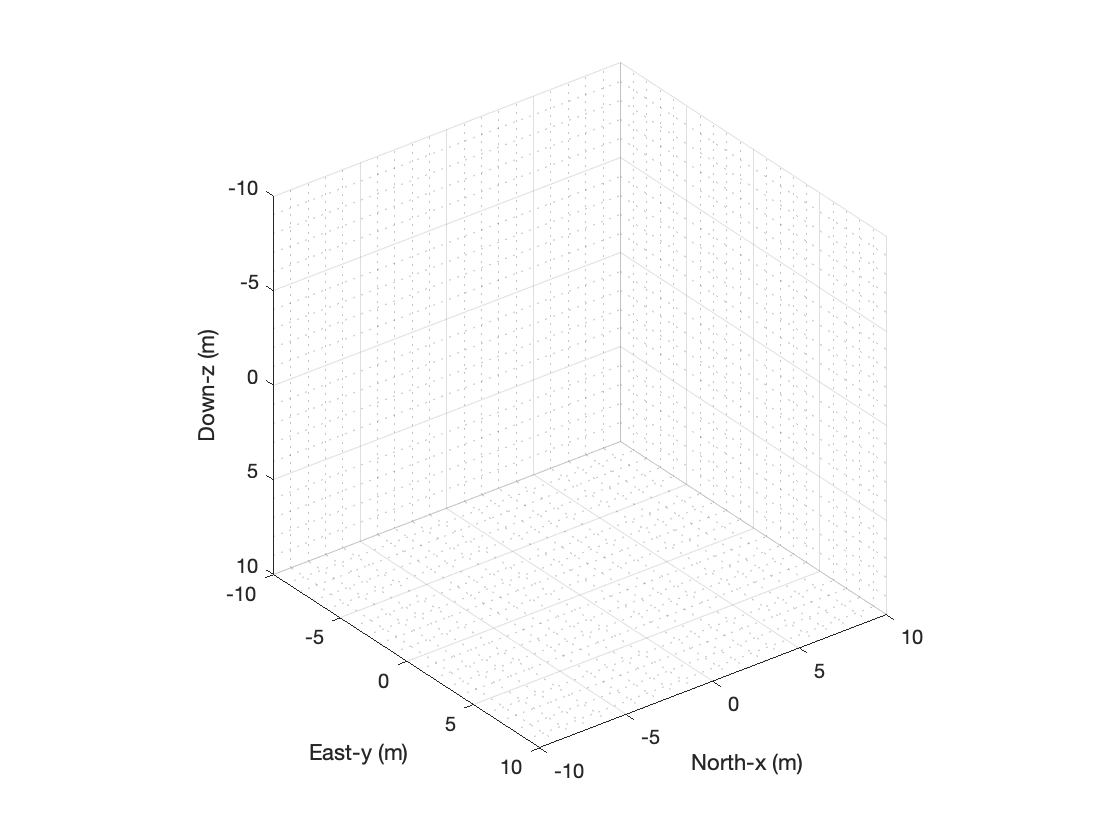

xlabel("North-x (m)")
ylabel("East-y (m)")
zlabel("Down-z (m)");
a = 10.00;
xlim([-a a])
ylim([-a a])
zlim([-a a])
pos = [0 0 0];

%Create orientation matrix
for i = 2:limit
    q = fuse(acceleration(i, :), gyroscope(i, :), magnetometer(i, :));
    pos = position(i,:);
    set(pp, Orientation = q, Position = pos);
    drawnow
end


%Start reading values and then fuse them
%c = size(time, 2)
%for i = 1:c
 %   q = fuse(acceleration(i, :), gyroscope(i, :), magnetometer(i, :));
  %  plot(time(i), eulerd(q, "ZYX", "frame"), "MarkerSize", 20);
%end

A = [1 0 0 dt 0 0 0 0 0 0 0 0;
     0 1 0 0 dt 0 0 0 0 0 0 0;
     0 0 1 0 0 dt 0 0 0 0 0 0;
     0 0 0 1 0 0 0 0 0 0 0 0;
     0 0 0 0 1 0 0 0 0 0 0 0;
     0 0 0 0 0 1 0 0 0 0 0 0;
     0 0 0 0 0 0 1 0 0 dt 0 0;
     0 0 0 0 0 0 0 1 0 0 dt 0;
     0 0 0 0 0 0 0 0 1 0 0 dt;
     0 0 0 0 0 0 0 0 0 1 0 0;
     0 0 0 0 0 0 0 0 0 0 1 0;
     0 0 0 0 0 0 0 0 0 0 0 1];

B = [0.5*dt^2 0 0 0 0 0;
     0 0.5*dt^2 0 0 0 0;
     0 0 0.5*dt^2 0 0 0;
     dt 0 0 0 0 0;
     0 dt 0 0 0 0;
     0 0 dt 0 0 0;
     0 0 0 0.5*dt^2 0 0;
     0 0 0 0 0.5*dt^2 0;
     0 0 0 0 0 0.5*dt^2;
     0 0 0 dt 0 0;
     0 0 0 0 dt 0;
     0 0 0 0 0 dt];

C = [0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;]